# Data-Driven Control Homework - SIDRA 2024 - Giorgio Ridolfi - extra

clc
close all
clear all
rng(1);
addpath("/home/gio/Scrivania/lezioni/lezione_assignment_datadriven_sidra_2024/datadriven_sidra2024/cvx/")
cvx_setup

---------------------------------------------------------------------------
CVX: Software for Disciplined Convex Programming       (c)2014 CVX Research
Version 2.2, Build   9 (a0a77590)                  Tue Apr 23 19:28:09 2024
---------------------------------------------------------------------------
Installation info:
    Path: /home/gio/Scrivania/lezioni/lezione_assignment_datadriven_sidra_2024/datadriven_sidra2024/cvx
    MATLAB version: 24.1 (R2024a)
    OS: Linux amd64 version 6.9.3-76060903-generic
    Java version: 1.8.0_202
Verfying CVX directory contents:
    No missing files.
Preferences: 
    Path: /root/.matlab/cvx_prefs.mat
---------------------------------------------------------------------------
Setting CVX paths...done.
Saving updated path...done.
Searching for solvers...5 shims found.
2 solvers initialized (* = default):
 *  SDPT3    4.0        {cvx}/sdpt3
    SeDuMi   1.02,      {cvx}/sedumi
3 solvers skipped:
    GLPK                
        Could not find a GLPK 



% Dimensions of system
nx = 3 ;
nu=1;
% Length of the input sequence
T = 10 ;

% Generating the input sequence u on [0,T-1] taking values in the interval
% [-1,1]^m in the form of an m x T matrix [u(0) u(1) .... u(T-1)]
magnitude=0.1;
aux=zeros(nu,T);
aux(:)=magnitude;
u(1:nu,1:T)=(2*magnitude).*rand(nu,T)-aux;
% Arranging the samples in the Hankel matrix U0 on [0,T-1]
for j=1:T-nu+1
    for i=1:nu
        U0((i-1)*nu+1:(i-1)*nu+nu,j)=u(1:nu, j+i-1);
    end
end
% If rank(U0)= m*L then the sequence u(0),...u(T-1) is PE of order L
if rank(U0) == nu*nu
    disp("input sequence is PE");
end

input sequence is PE


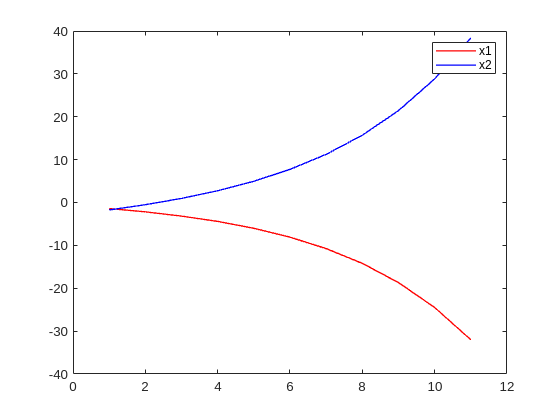

% Example 1
% Robot initial configuration and necessary data structures

x = zeros(nx,T+1);
x_dot = x;

 mag = 0.1; % magnitude of initial conditions
% x(:,1) = [ (2*mag).*rand(2,1)-mag; 0 ];
x(:,1)= [-1.40997503421309;
-1.74728260275247;
0 ];
Z0 = zeros(1,T+1);
Z0(1) = cos(x(1,1));

B = [ 0 0 1]' ;
A = [ 4.25 1 -0.25 -1;
      -6.25 -2 0 0 ;
      0 0 0 0];


deltat = 0.1 ;

for t = 1 : T
    x1 = x(1,t);
    x2 = x(2,t);
    x3 = x(3,t);
    Z_x = [ x1 x2 x3 x1*x3 ]';
    Z0(t) = x1*x3;    

    % Collect state derivative
    x_dot(:,t) = A*Z_x + B*u(t);
    % Collect state
    x(:,t+1) = x(:,t) + x_dot(:,t)*deltat;
end

% Plot code taken from 
% https://github.com/zjhurug/codes-for-contraction-paper/blob/main/Ex1_one_link_robot_arm/one_link_robot_arm.m 
% and slightly modified
figure
title('Open loop')
plot(x(1,:),'r','LineWidth',1);
hold on;
plot(x(2,:),'b','LineWidth',1);
hold on;
legend('x1 ','x2');


U0 = u(1:end);
X0 = x(:,1:end-1);
X1 = x_dot(:,1:end-1);
Z0 = Z0(1:end-1);
Z0 = [ X0 ; Z0 ]; 
s = size(Z0 , 1 ); % s number of nonlinear terms in Z(x)
% Sanity check, should return zeros
X1 - ( A*Z0 + B*U0 ) 

ans =      0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0



RQ = [ 1.5 0  0 ; 0  0 0 ; 0 0 1.5] ;

cvx_begin sdp
variable P1(nx,nx) symmetric
variable Y1(T,nx)
variable G2(T,s-nx)
variable a
P1 >= 0*eye(nx);
a >= 0;
Z0*Y1 == [P1;zeros(s-nx,nx)];
[X1*Y1+(X1*Y1)'+a*eye(nx) X1*G2 P1*RQ;
     (X1*G2)' -eye(s-nx) zeros(s-nx,nx);
     (P1*RQ)' zeros(nx,s-nx) -eye(nx)] <= 0;
Z0*G2 == [zeros(nx,s-nx);eye(s-nx)];
cvx_end

 
Calling SDPT3 4.0: 50 variables, 46 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 46
 dim. of sdp    var  = 10,   num. of sdp  blk  =  2
 dim. of linear var  =  1
 dim. of free   var  = 15 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.5e+03|5.0e+02|2.8e+05| 4.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.814|0.930|6.6e+02|3.5e+01|6.1e+03| 4.134048e+01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.858|0.805|9.3e+01|6.9e+00|7.5e+02| 4.801458e+01  0.000000e+00| 0:0:00

G1 = Y1/P1;

G  = [G1 G2];
K  = U0*G ;

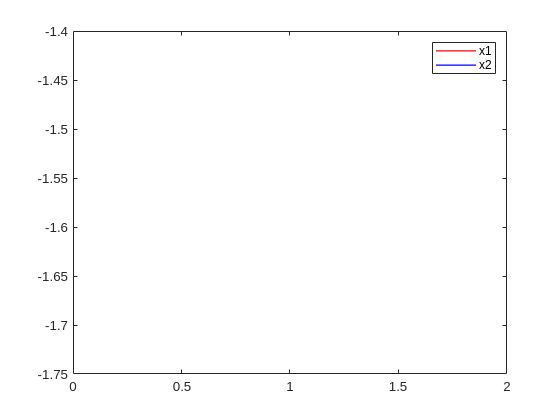


% Simulate controlled sysstem (for a longer period of time)
T = 10*T ;
x = zeros(nx,T+1);
x_dot = x;

% x(:,1) = [ (2*mag).*rand(2,1)-mag; 0 ];

x(:,1)= [-1.40997503421309;
-1.74728260275247;
0 ];
Z0 = zeros(1,T+1);
Z0(1) = cos(x(1,1));

deltat = 0.01 ; 
for t = 1 : T
    x1 = x(1,t);
    x2 = x(2,t);
    x3 = x(3,t);
    Z_x = [ x1 x2 x3 x1*x3 ]';
    Z0(t) = x1*x3;    

    % Collect state derivative
    x_dot(:,t) = (A+B*K)*Z_x ;
    % Collect state
    x(:,t+1) = x(:,t) + x_dot(:,t)*deltat;
end

% Plot code taken from 
% https://github.com/zjhurug/codes-for-contraction-paper/blob/main/Ex1_one_link_robot_arm/one_link_robot_arm.m 
% and slightly modified
figure
title('Open loop')
plot(x(1,:),'r','LineWidth',1);
hold on;
plot(x(2,:),'b','LineWidth',1);
hold on;
legend('x1 ','x2');